### Fig 10

clear; clc;


K = 1;              
Omega = 50;        
alpha = 2;
delta = 0.04;      
P0_fixed = 0.1;     
A = 0.8;
f = 0.05;

num_r = 20;
num_a = 20;
r_vec = linspace(0.1, 1.9, num_r);       
a_vec = logspace(log10(0.02), log10(0.2), num_a);  


grid_size = 100;
B0_vec = logspace(-2, log10(0.5), grid_size);  % B0: 0.01 ~ 0.5
I0_vec = logspace(-2, log10(0.5), grid_size);  % I0: 0.01 ~ 0.5
total_points = grid_size^2;


t_final = 500;
extinct_thres = 1e-8;

% ODE
options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.1);
tspan = [0, t_final];


survival_ratio_map = zeros(num_r, num_a);


fprintf('Starting 20x20 parameter scan...\n');

Starting 20x20 parameter scan...


for r_idx = 1:num_r
    r = r_vec(r_idx);
    fprintf('Processing r = %.3f (%d/%d)\n', r, r_idx, num_r);
    
    for a_idx = 1:num_a
        a = a_vec(a_idx);
        

        state_matrix = zeros(grid_size, grid_size);
        

        parfor i = 1:grid_size
            for j = 1:grid_size
                B0 = B0_vec(j);
                I0 = I0_vec(i);
                y0 = [B0; I0; P0_fixed];
                
                [~, y] = ode15s(@(t,y) fluctuate_1B(t, y, A,f,r, K, a, Omega,alpha, delta), ...
                                tspan, y0, options);

                n = size(y, 1);
                last_y_B = y(floor(n*0.9):end, 1);
                

                if min(last_y_B) >= extinct_thres
                    state_matrix(i, j) = 1;
                else
                    state_matrix(i, j) = 0; 
                end
            end
        end

        survival_ratio_map(r_idx, a_idx) = sum(state_matrix(:)) / total_points;
        

        if mod(a_idx, ceil(num_a/10)) == 0 || a_idx == num_a
            fprintf('  -> a = %.4f, survival = %.3f\n', a, survival_ratio_map(r_idx, a_idx));
        end
    end
end

Processing r = 0.100 (1/20)


Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


  -> a = 0.0226, survival = 0.996
  -> a = 0.0288, survival = 0.966
  -> a = 0.0367, survival = 0.858
  -> a = 0.0467, survival = 0.735
  -> a = 0.0595, survival = 0.623
  -> a = 0.0759, survival = 0.517
  -> a = 0.0967, survival = 0.413
  -> a = 0.1232, survival = 0.325
  -> a = 0.1570, survival = 0.242
  -> a = 0.2000, survival = 0.155


Processing r = 0.195 (2/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 0.967
  -> a = 0.0367, survival = 0.878
  -> a = 0.0467, survival = 0.768
  -> a = 0.0595, survival = 0.643
  -> a = 0.0759, survival = 0.528
  -> a = 0.0967, survival = 0.417
  -> a = 0.1232, survival = 0.310
  -> a = 0.1570, survival = 0.220
  -> a = 0.2000, survival = 0.141


Processing r = 0.289 (3/20)


  -> a = 0.0226, survival = 0.990
  -> a = 0.0288, survival = 0.938
  -> a = 0.0367, survival = 0.847
  -> a = 0.0467, survival = 0.755
  -> a = 0.0595, survival = 0.626
  -> a = 0.0759, survival = 0.492
  -> a = 0.0967, survival = 0.376
  -> a = 0.1232, survival = 0.268
  -> a = 0.1570, survival = 0.176
  -> a = 0.2000, survival = 0.110


Processing r = 0.384 (4/20)


  -> a = 0.0226, survival = 0.963
  -> a = 0.0288, survival = 0.879
  -> a = 0.0367, survival = 0.776
  -> a = 0.0467, survival = 0.683
  -> a = 0.0595, survival = 0.562
  -> a = 0.0759, survival = 0.425
  -> a = 0.0967, survival = 0.299
  -> a = 0.1232, survival = 0.193
  -> a = 0.1570, survival = 0.111
  -> a = 0.2000, survival = 0.058


Processing r = 0.479 (5/20)


  -> a = 0.0226, survival = 0.928
  -> a = 0.0288, survival = 0.799
  -> a = 0.0367, survival = 0.677
  -> a = 0.0467, survival = 0.568
  -> a = 0.0595, survival = 0.489
  -> a = 0.0759, survival = 0.385
  -> a = 0.0967, survival = 0.266
  -> a = 0.1232, survival = 0.166
  -> a = 0.1570, survival = 0.070
  -> a = 0.2000, survival = 0.025


Processing r = 0.574 (6/20)


  -> a = 0.0226, survival = 0.891
  -> a = 0.0288, survival = 0.709
  -> a = 0.0367, survival = 0.560
  -> a = 0.0467, survival = 0.474
  -> a = 0.0595, survival = 0.392
  -> a = 0.0759, survival = 0.299
  -> a = 0.0967, survival = 0.208
  -> a = 0.1232, survival = 0.114
  -> a = 0.1570, survival = 0.043
  -> a = 0.2000, survival = 0.012


Processing r = 0.668 (7/20)


  -> a = 0.0226, survival = 0.860
  -> a = 0.0288, survival = 0.615
  -> a = 0.0367, survival = 0.467
  -> a = 0.0467, survival = 0.401
  -> a = 0.0595, survival = 0.366
  -> a = 0.0759, survival = 0.310
  -> a = 0.0967, survival = 0.213
  -> a = 0.1232, survival = 0.113
  -> a = 0.1570, survival = 0.035
  -> a = 0.2000, survival = 0.005


Processing r = 0.763 (8/20)


  -> a = 0.0226, survival = 0.844
  -> a = 0.0288, survival = 0.520
  -> a = 0.0367, survival = 0.409
  -> a = 0.0467, survival = 0.363
  -> a = 0.0595, survival = 0.337
  -> a = 0.0759, survival = 0.284
  -> a = 0.0967, survival = 0.176
  -> a = 0.1232, survival = 0.082
  -> a = 0.1570, survival = 0.022
  -> a = 0.2000, survival = 0.004


Processing r = 0.858 (9/20)


  -> a = 0.0226, survival = 0.850
  -> a = 0.0288, survival = 0.448
  -> a = 0.0367, survival = 0.364
  -> a = 0.0467, survival = 0.323
  -> a = 0.0595, survival = 0.295
  -> a = 0.0759, survival = 0.233
  -> a = 0.0967, survival = 0.140
  -> a = 0.1232, survival = 0.059
  -> a = 0.1570, survival = 0.007
  -> a = 0.2000, survival = 0.002


Processing r = 0.953 (10/20)


  -> a = 0.0226, survival = 0.890
  -> a = 0.0288, survival = 0.410
  -> a = 0.0367, survival = 0.328
  -> a = 0.0467, survival = 0.289
  -> a = 0.0595, survival = 0.241
  -> a = 0.0759, survival = 0.204
  -> a = 0.0967, survival = 0.143
  -> a = 0.1232, survival = 0.061
  -> a = 0.1570, survival = 0.009
  -> a = 0.2000, survival = 0.000


Processing r = 1.047 (11/20)


  -> a = 0.0226, survival = 0.982
  -> a = 0.0288, survival = 0.381
  -> a = 0.0367, survival = 0.298
  -> a = 0.0467, survival = 0.260
  -> a = 0.0595, survival = 0.218
  -> a = 0.0759, survival = 0.208
  -> a = 0.0967, survival = 0.152
  -> a = 0.1232, survival = 0.071
  -> a = 0.1570, survival = 0.008
  -> a = 0.2000, survival = 0.001


Processing r = 1.142 (12/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 0.364
  -> a = 0.0367, survival = 0.273
  -> a = 0.0467, survival = 0.235
  -> a = 0.0595, survival = 0.216
  -> a = 0.0759, survival = 0.207
  -> a = 0.0967, survival = 0.154
  -> a = 0.1232, survival = 0.075
  -> a = 0.1570, survival = 0.016
  -> a = 0.2000, survival = 0.002


Processing r = 1.237 (13/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 0.354
  -> a = 0.0367, survival = 0.252
  -> a = 0.0467, survival = 0.214
  -> a = 0.0595, survival = 0.200
  -> a = 0.0759, survival = 0.195
  -> a = 0.0967, survival = 0.152
  -> a = 0.1232, survival = 0.071
  -> a = 0.1570, survival = 0.019
  -> a = 0.2000, survival = 0.001


Processing r = 1.332 (14/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 0.358
  -> a = 0.0367, survival = 0.235
  -> a = 0.0467, survival = 0.194
  -> a = 0.0595, survival = 0.182
  -> a = 0.0759, survival = 0.178
  -> a = 0.0967, survival = 0.139
  -> a = 0.1232, survival = 0.065
  -> a = 0.1570, survival = 0.016
  -> a = 0.2000, survival = 0.003


Processing r = 1.426 (15/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 0.375
  -> a = 0.0367, survival = 0.224
  -> a = 0.0467, survival = 0.178
  -> a = 0.0595, survival = 0.165
  -> a = 0.0759, survival = 0.163
  -> a = 0.0967, survival = 0.127
  -> a = 0.1232, survival = 0.050
  -> a = 0.1570, survival = 0.008
  -> a = 0.2000, survival = 0.002


Processing r = 1.521 (16/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 0.403
  -> a = 0.0367, survival = 0.215
  -> a = 0.0467, survival = 0.164
  -> a = 0.0595, survival = 0.151
  -> a = 0.0759, survival = 0.148
  -> a = 0.0967, survival = 0.109
  -> a = 0.1232, survival = 0.046
  -> a = 0.1570, survival = 0.005
  -> a = 0.2000, survival = 0.002


Processing r = 1.616 (17/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 0.454
  -> a = 0.0367, survival = 0.208
  -> a = 0.0467, survival = 0.151
  -> a = 0.0595, survival = 0.137
  -> a = 0.0759, survival = 0.131
  -> a = 0.0967, survival = 0.093
  -> a = 0.1232, survival = 0.045
  -> a = 0.1570, survival = 0.005
  -> a = 0.2000, survival = 0.002


Processing r = 1.711 (18/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 0.557
  -> a = 0.0367, survival = 0.205
  -> a = 0.0467, survival = 0.140
  -> a = 0.0595, survival = 0.125
  -> a = 0.0759, survival = 0.111
  -> a = 0.0967, survival = 0.081
  -> a = 0.1232, survival = 0.046
  -> a = 0.1570, survival = 0.009
  -> a = 0.2000, survival = 0.001


Processing r = 1.805 (19/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 0.718
  -> a = 0.0367, survival = 0.205
  -> a = 0.0467, survival = 0.131
  -> a = 0.0595, survival = 0.112
  -> a = 0.0759, survival = 0.089
  -> a = 0.0967, survival = 0.074
  -> a = 0.1232, survival = 0.050
  -> a = 0.1570, survival = 0.008
  -> a = 0.2000, survival = 0.000


Processing r = 1.900 (20/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 0.212
  -> a = 0.0467, survival = 0.122
  -> a = 0.0595, survival = 0.101
  -> a = 0.0759, survival = 0.073
  -> a = 0.0967, survival = 0.072
  -> a = 0.1232, survival = 0.055
  -> a = 0.1570, survival = 0.009
  -> a = 0.2000, survival = 0.001


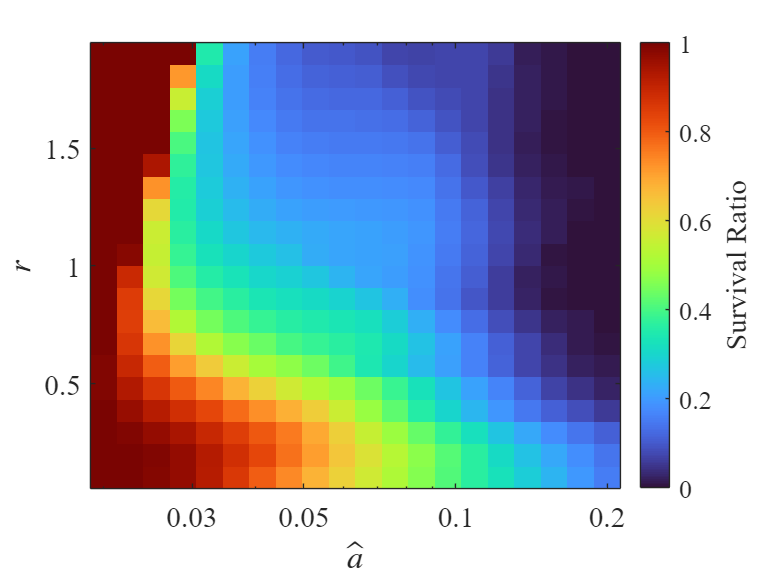

% ===== Visualization =====
figure;
imagesc(a_vec, r_vec, survival_ratio_map);
hcb = colorbar('Location','eastoutside');
colormap("turbo");

hcb.Label.String = 'Survival Ratio';
hcb.Label.FontSize = 16;
hcb.Label.FontName = 'Times New Roman';
xlabel('$\hat{a}$', 'Interpreter', 'latex', 'FontSize', 18, 'FontName', 'Times New Roman');
ylabel('$r$ ', 'Interpreter', 'latex', 'FontSize', 18, 'FontName', 'Times New Roman');
%title('Survival Ratio (Fraction of Initial Conditions Surviving)', 'FontSize', 20, 'FontName', 'Times New Roman');


ax = gca;
ax.XScale = 'log';
xticks([0.03, 0.05, 0.1, 0.2]);
set(ax, 'FontSize', 16, 'FontName', 'Times New Roman');

ylim([min(r_vec) max(r_vec)]);
set(gca, 'YDir', 'normal'); 

grid off;
box on;
axis tight;

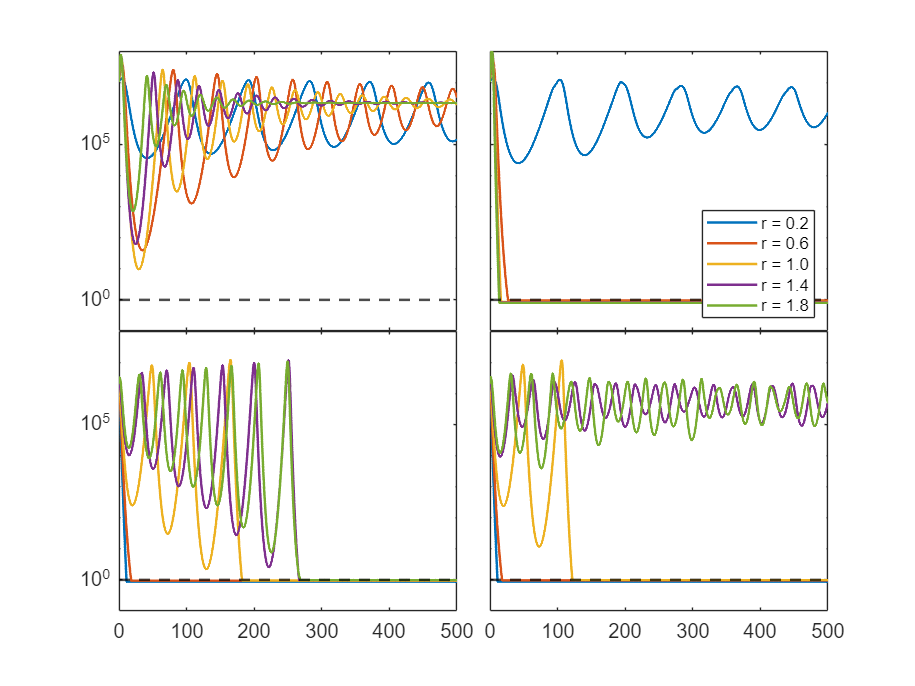


clear;clc;
K = 1;                   
a_values = [0.038, 0.12]; 
Omega = 50;              
alpha = 2;
delta = 0.04;            
A = 0.8;
f = 0.05;
r_values = [0.2, 0.6, 1.0, 1.4, 1.8];  
tspan = [0 500];


options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.1);


B0_1 = 0.1; I0_1 = 0.05; P0_1 = 0.1;
y0_1 = [B0_1; I0_1; P0_1];

B0_2 = 0.02; I0_2 = 0.3; P0_2 = 0.1;
y0_2 = [B0_2; I0_2; P0_2];

colors = lines(length(r_values));


figWidth_cm = 8;
figHeight_cm = 6;
dpi = 300;
figure('Position', [100, 100, figWidth_cm*dpi/2.54, figHeight_cm*dpi/2.54]);

tl = tiledlayout(2, 2, 'TileSpacing', 'tight');


axes_handles = cell(2, 2);


y0s = {y0_1, y0_2};

for i_row = 1:2
    for j_col = 1:2
        ax = nexttile;
        axes_handles{i_row, j_col} = ax; 
        hold(ax, 'on');
        
        y0 = y0s{i_row};
        a = a_values(i_row);
        
        for k = 1:length(r_values)
            r = r_values(k);
            if j_col == 1
                [t, y] = ode15s(@(t,y) ode1B(t, y, r, K, a, Omega, alpha, delta), tspan, y0, options);
            else
                [t, y] = ode15s(@(t,y) fluctuate_1B(t, y, A, f, r, K, a, Omega, alpha, delta), tspan, y0, options);
            end
            
            y_scaled = y * 1e8;
            plot(ax, t, y_scaled(:,1), '-', 'Color', colors(k,:), 'LineWidth', 1.5);
            ylim([10^-1,10^8]);
            xlim([0,500]);
        end

        yline(ax, 1, '--k', 'LineWidth', 1.5);

        ax.YScale = 'log';
        grid(ax, 'off');
        box(ax, 'on');
        ax.FontSize = 12;
    end
end


axes_handles{1, 1}.XTickLabel = {};
axes_handles{1, 2}.XTickLabel = {};


axes_handles{1, 2}.YTickLabel = {};
axes_handles{2, 2}.YTickLabel = {};



ax_12 = axes_handles{1, 2};
legend_strings = arrayfun(@(r) sprintf('r = %.1f', r), r_values, 'UniformOutput', false);
legend(ax_12, legend_strings, 'Location', 'southeast', 'FontSize', 10);